clearvars % Clear Workspace
close all % Close ALL open plots

% Persistent variables to simulate global state
global Server

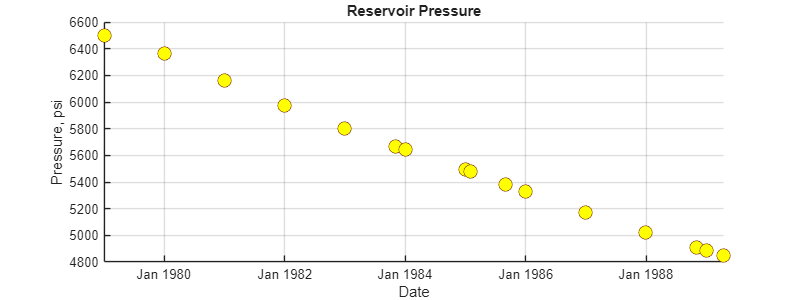

Pred_mode = 0; % 0=No-Optimisation / 1=Optimised

Server = actxserver('PX32.OpenServer.1');  % COM object creation

NumSteps = str2double(DoGAPFunc("GAP.PREDINIT()"));

Dates_m = NaT(NumSteps, 1);
Results_m = zeros(NumSteps,4);

date_i = Server.GetValue("GAP.MOD[{PROD}].PREDINFO.START");
date_ii = str2double(date_i);
dt_i = datetime(date_ii, 'ConvertFrom', 'datenum');
dt_i = datetime(1978,1,1);
dt_f = datetime(2000,1,1);

% *** PLOTS ***
p1= GAP_Plot(Dates_m(:, 1),Results_m(:, 1),'Reservoir Pressure','Date','Pressure, psi','yy');

p2= GAP_Plot(Dates_m(:, 1),Results_m(:, 2),'Gas','Date','Gas Rate, MMscfd','rr');

p3= GAP_Plot(Dates_m(:, 1),Results_m(:, 3),'Oil','Date','Oil Rate, bpd','gg');

p4= GAP_Plot(Dates_m(:, 1),Results_m(:, 4),'Water','Date','Water Rate, bpd','bb');

j = 0;

    while ~strcmp(DoGAPFunc("GAP.PREDDOSTEP(" + Pred_mode + ")"), "0")
        x = j + 1;
        DateRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES.DATES[" + j +"]");
        dt = datetime(str2double(DateRes), 'ConvertFrom', 'datenum');
        
        % Adjust the year to interpret it as 1900s instead of 0000s
        if year(dt) < 1900 
            dt.Year = dt.Year + 1900; % Add 1900 to the year
        end
        Dates_m(x,1) = dt;
        
        Pr = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[" + j + "].RESPRES");
        Qg = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[" + j + "].GASRATE");
        Qo = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[" + j + "].OILRATE");
        Qw = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[" + j + "].WATRATE");
        
        Results_m(x, 1)= str2double(Pr);
        Results_m(x, 2)= str2double(Qg);
        Results_m(x, 3)= str2double(Qo);
        Results_m(x, 4)= str2double(Qw);
        
        set(p1,'XData',Dates_m(:, 1),'YData',Results_m(:, 1)) % Reservoir Pressure
        set(p2,'XData',Dates_m(:, 1),'YData',Results_m(:, 2)) % Gas Rate
        set(p3,'XData',Dates_m(:, 1),'YData',Results_m(:, 3)) % Oil Rate
        set(p4,'XData',Dates_m(:, 1),'YData',Results_m(:, 4)) % Water Rate
        
        %disp(Pr)
        %disp(j)
        j = j + 1;
    end

    DoSlowCmd("GAP.PREDEND(0)");

% *** Import final results
DateRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES.DATES[$]");
DateRes_m = datetime(str2double(split(DateRes, "|")), 'ConvertFrom', 'datenum');
DateRes_m.Year = DateRes_m.Year + 1900; % Add 1900 to the year

PrRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[$].RESPRES");
PrRes_m = str2double(split(PrRes, "|"));
set(p1,'XData',DateRes_m(:, 1),'YData',PrRes_m(:, 1)) % change the line data

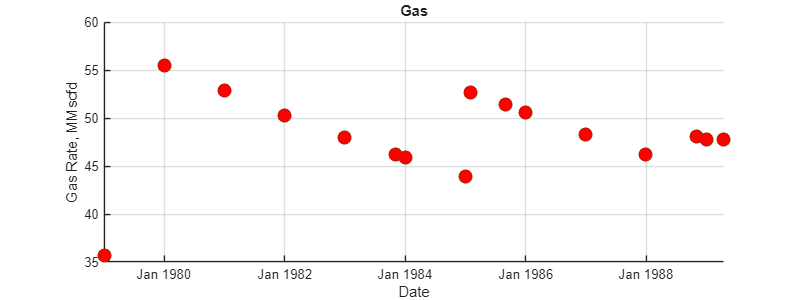


QgRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[$].GASRATE");
QgRes_m = str2double(split(QgRes, "|"));
set(p2,'XData',DateRes_m(:, 1),'YData',QgRes_m(:, 1)) % change the line data

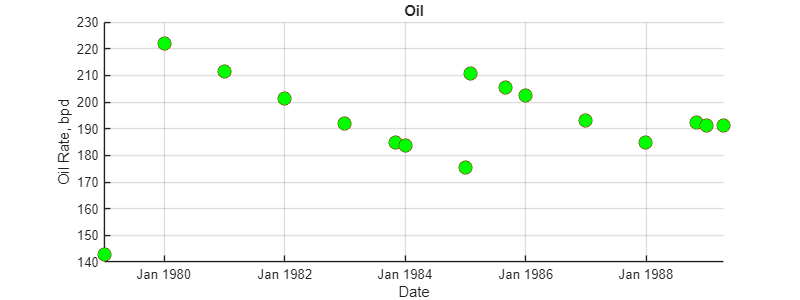


QoRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[$].OILRATE");
QoRes_m = str2double(split(QoRes, "|"));
set(p3,'XData',DateRes_m(:, 1),'YData',QoRes_m(:, 1)) % change the line data

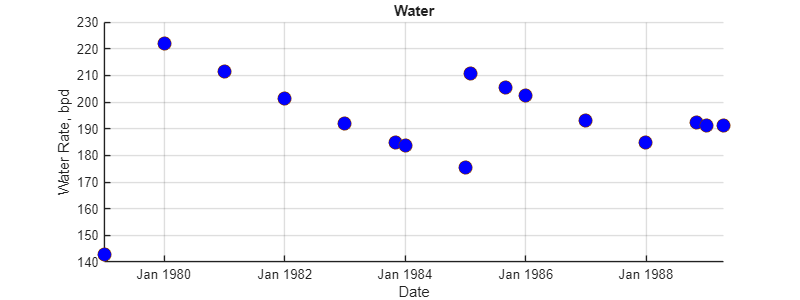


QwRes = Server.GetValue("GAP.MOD[{PROD}].TANK[0].PREDRES[$].WATRATE");
QwRes_m = str2double(split(QwRes, "|"));
set(p4,'XData',DateRes_m(:, 1),'YData',QoRes_m(:, 1)) % change the line data

Server = actxserver('PX32.OpenServer.1');  % COM object creation
        
Wells_Labels_str = Server.GetValue("GAP.MOD[{PROD}].WELL[$].Label");
Wells_Labels_str = extractBefore(Wells_Labels_str, strlength(Wells_Labels_str));
Wells_Labels_m = strsplit(Wells_Labels_str, "|");
[numRows, numColumns] = size(Wells_Labels_m);
Wells_index = reshape(1:numColumns, 1, numColumns);
array = 0:1:numColumns-1;

Well_Label_Selection = 'Well 1'

Well_Label_Selection = 'Well 1'

DateWells = Server.GetValue("GAP.MOD[{PROD}].WELL[{" + Well_Label_Selection + "}].PREDRES.DATES[$]");
DateWells = extractBefore(DateWells, strlength(DateWells));
DateRes_m = datetime(str2double(split(DateWells, "|")), 'ConvertFrom', 'datenum');
DateRes_m.Year = DateRes_m.Year + 1900; % Add 1900 to the year

function p = GAP_Plot(x, y, plotTitle, xLabel, yLabel,MarkerColor)
    switch MarkerColor
        case 'yy'
            Pcolor = [1 1 0];
        case 'rr'
            Pcolor = [1 0 0];
        case 'gg'
            Pcolor = [0 1 0];
        case 'bb'
            Pcolor = [0 0 1];
    end


% Create the plot
    %figure; % Open a new figure window
    %plot(x, y, 'LineWidth', 2); % Plot with thicker lines
    fig = figure('Position', [0, 0, 800, 300]); % create a figure
    ax = axes('Parent',fig); % create axes
    p = scatter(ax,x,y,100, 'MarkerEdgeColor',[0.5 0.2 0],'MarkerFaceColor',Pcolor);
    grid on; % Add grid for better readability
    
    % Add title and labels
    title(plotTitle, 'FontSize', 14);
    xlabel(xLabel, 'FontSize', 12);
    ylabel(yLabel, 'FontSize', 12);
    ax.XAxis.TickLabelFormat = 'MMM yyyy';
    % Customize appearance
    set(gca, 'FontSize', 10, 'Visible', 'on'); % Adjust axis font size
    %legend('Data', 'Location', 'best'); % Add a legend
end


function result = DoGAPFunc(Gv)
    %Server = actxserver('PX32.OpenServer.1');  % COM object creation
    global Server
    DoSlowCmd(Gv);
    result = Server.GetValue("GAP.LASTCMDRET");
    lErr = Server.GetLastError("GAP");
    if lErr > 0
        disp(Server.GetErrorDescription(lErr));
        Disconnect();
        error('Execution stopped due to error.');
    end
end

function DoSlowCmd(Cmd)
    %Server = actxserver('PX32.OpenServer.1');  % COM object creation
    global Server
    step = 0.001;
    %AppName = GetAppName(Cmd);
    AppName = 'GAP';
    lErr = Server.DoCommandAsync(Cmd);
    if lErr > 0
        disp(Server.GetErrorDescription(lErr));
        %Disconnect();
        error('Execution stopped due to error.');
    end

    while Server.IsBusy(AppName) > 0
        if step < 2
            step = step * 2;
        end
        starttime = tic;
        while toc(starttime) < step
            drawnow;  % Simulates DoEvents
        end
    end

    %AppName = GetAppName(Cmd);
    AppName = 'GAP';
    lErr = Server.GetLastError(AppName);
    if lErr > 0
        disp(Server.GetErrorDescription(lErr));
        %Disconnect();
        error('Execution stopped due to error.');
    end
end

